## Parte 2

[x,t,num,den] = exame2(2999,1)

x =     1.8010    0.5823   -0.5729   -0.7621   -0.7983   -0.6011   -0.4387   -0.1684    0.0089    0.9493    1.8010    0.5823   -0.5729   -0.7621   -0.7983   -0.6011   -0.4387   -0.1684    0.0089    0.9493    1.8010    0.5823   -0.5729   -0.7621   -0.7983   -0.6011   -0.4387   -0.1684    0.0089    0.9493    1.8010    0.5823   -0.5729   -0.7621   -0.7983   -0.6011   -0.4387   -0.1684    0.0089    0.9493    1.8010    0.5823   -0.5729   -0.7621   -0.7983   -0.6011   -0.4387   -0.1684    0.0089    0.9493


t =          0    0.0025    0.0050    0.0075    0.0100    0.0125    0.0150    0.0175    0.0200    0.0225    0.0250    0.0275    0.0300    0.0325    0.0350    0.0375    0.0400    0.0425    0.0450    0.0475    0.0500    0.0525    0.0550    0.0575    0.0600    0.0625    0.0650    0.0675    0.0700    0.0725    0.0750    0.0775    0.0800    0.0825    0.0850    0.0875    0.0900    0.0925    0.0950    0.0975    0.1000    0.1025    0.1050    0.1075    0.1100    0.1125    0.1150    0.1175    0.1200    0.1225


num =     0.0466    0.1863    0.2795    0.1863    0.0466


den =     1.0000   -0.7821    0.6800   -0.1827    0.0301


a = diff(t);


### 1.

variavel a = periodo de amostragem

fa = 1./a(1,1);

fprintf('Frequência de amostragem = %d', fa);

Frequência de amostragem = 400

### 2.

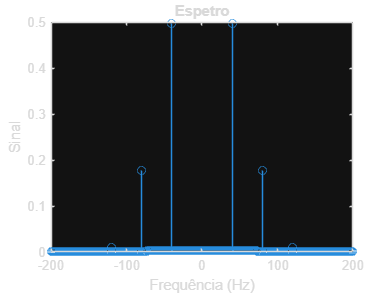

y = filter(num,den,x);
espetro(y,1/fa);

### 3.

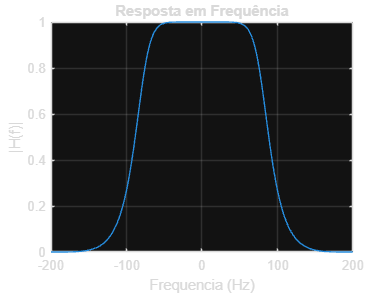

respfreq(num,den,fa);

4.

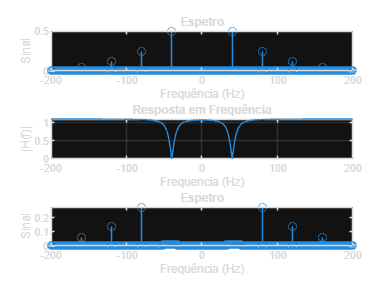

freq_escolhida = 40; % hz

R = 0.9;
teta = 2*pi*(freq_escolhida/fa);
num = [1 -2*cos(teta) 1];
den = [1 -2*R*cos(teta) R^2];


figure;
subplot(3,1,1);
[X,f] = espetro(x,1/fa);

subplot(3,1,2);
respfreq(num,den,fa);

subplot(3,1,3);
h = filter(num,den,x);
[H,f1] = espetro(h,1/fa);